# Controllore PolePlacement

### Modello in esame


$$\begin{cases}
\dot x_1 =x_2 \\
\dot{x_2} = -\frac{g}{l} sin x_1- \frac{b}{ml^2}x_2+ \frac{u(t)}{ml^2}\\
y=x_1
\end{cases}$$


Sarà usato un controllore state-feedback del tipo: $u = -Kx + K_r r$. In particolare, il sistema sarà linearizzato intorno al punto di equilibrio instabile $\left\lbrack \pi ;0\right\rbrack$ ed una volta ottenute le matrici $A,B,C,D$ si procederà con il test della raggiungibilità per il quale ricordiamo essere necessarie solo $A,B$. I passi successivi saranno il piazzamento dei poli a ciclo chiuso tramite la tecnica del pole placement e la verifica delle performance.

clear all, clc , close all
mkdir ('Risultati Pole Placement')

syms x1 x2 u
    m = 1; 
    l = 1;
    b = 0.1;
    g = 9.81;
    r = pi;
    x_e=[pi,0];
% Definisci le equazioni del sistema
    x1_dot = x2;
    x2_dot = (-g/l)*sin(x1) - ((b*x2)/(m*l^2)) + (u/(m*l^2));

% Definisci il vettore di stato e il vettore di input
X = [x1; x2];
U = u;

% Calcola le matrici A, B, C e D
A = jacobian([x1_dot; x2_dot], X);
B = jacobian([x1_dot; x2_dot], U);

% Sostituisci i valori numerici delle costanti
A = subs(A, {g, l, b, m}, {9.81, 1, 0.1, 1});
B = subs(B, {g, l, b, m}, {9.81, 1, 0.1, 1});
% Visualizza le matrici A, B
disp('Matrice A:');

Matrice A:


disp(A); 

$$\left(\begin{array}{cc} 0 & 1\\ -\frac{981\,\cos\left(x_{1}\right)}{100} & -\frac{1}{10} \end{array}\right)$$

disp('Matrice B:');

Matrice B:


disp(B);

$$\left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Il quale nel nostro caso dopo aver linearizzato intorno al punto di equilibrio instabile diventa: 


$$
A =\left(\begin{array}{cc} 0 & 1\\ 9.81 & -0.1 \end{array}\right)\\ B=  \left(\begin{array}{cc} 0 \\ 1 \end{array}\right) \\
C=\left(\begin{array}{cc}1 & 0 \end{array}\right)
$$


#### Analisi raggiungibilità

 A=[0 1;
    9.81 -1/10];
B=[0;1];
C=[1 0];
D=0;

In particolare si ricorda del mapping tra il nostro sistema linearizzato e sistema non linearizzato, dove il riferimento a $\pi$del secondo corrisponde ad un riferimento a $0$ del primo.

In virtù di questo remark il controllore del caso lineare: $u=-\textrm{Kx}+K_r r$ diventa: $u-u_e =-K\left(x-x_e \right)+K_r \left(r_{\textrm{nl}} -\pi \;\right)\to u=-K_1 \left(x_1 -x_{1_e } \right)-K_2 \left(x_2 -x_{2_e } \right)+K_r \left(\pi -\pi \right)+u_e$ nel quale sostituendo i valori in questione si ottiene: $u=-K_1 \left(x_1 -\pi \right)-K_2 x_2$ in quanto $u_e =0,x_{2_e } =0$.

Successivamente si è analizzata la raggiungibilità del sistema tramite la matrice di raggiungibilità $W_R$

Wr = [B A*B];
% In alternativa anche con ctrb(A,B), comando che data la matrice A e B da
% direttamente la matrice di controllabilità
disp('Matrice Wr:');

Matrice Wr:


disp(Wr); 

         0    1.0000
    1.0000   -0.1000



rank(Wr);
%dal momento che il rango è 2 possiamo dire che il sistema è controllabile.
%Quindi possiamo sviluppare un controllore per il sistema.

## Pole placement

Il posizionamento dei poli è un metodo per calcolare la matrice di guadagno utilizzata per assegnare i poli a ciclo chiuso in posizioni specifiche, garantendo così la stabilità del sistema. Le posizioni dei poli a ciclo chiuso hanno un impatto diretto sulle caratteristiche delle risposte temporali, quali tempo di salita, tempo di assestamento e oscillazioni transitorie.

Calcolando gli autovalori di A notiamo che non hanno tutti lo stesso segno, quindi il polinomio non è stabile. In realtà, ciò era prevedibile dal momento che la linearizzazione è stata effettuata proprio intorno al punto di equilibrio instabile $\left\lbrack \pi ;0\right\rbrack$(posizione verticale alta del pendolo).

eig(A); %autovalori pari a:3.0825 e -3.1825 

Useremo il comando "*place*":

Per un dato vettore $p$ con posizione desiderata dei poli autoconiugati a ciclo chiuso, `place` calcola una matrice di guadagno $K$ tale che il feedback di stato $ u = –Kx$ ponga i poli nelle posizioni $p$. In altre parole, gli autovalori di $A – BK $corrisponderanno alle voci di $p$.

[`K`](https://www.mathworks.com/help/releases/R2023b/control/ref/place.html?doclanguage=it&nocookie=true&prodfilter=ML%20SL%20CT%20DS%20AR%20RO%20RR%20SG%20SS%20MS%20SM&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DQJ94RA%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=XMPBHV&container=jshelpbrowser#mw_840355ae-b848-4a6f-984e-79ee2f5a6a8c) `= place(`[`A`](https://www.mathworks.com/help/releases/R2023b/control/ref/place.html?doclanguage=it&nocookie=true&prodfilter=ML%20SL%20CT%20DS%20AR%20RO%20RR%20SG%20SS%20MS%20SM&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DQJ94RA%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=XMPBHV&container=jshelpbrowser#mw_59e810f4-0d38-4f33-a278-8bab9e3cb195)`,`[`B`](https://www.mathworks.com/help/releases/R2023b/control/ref/place.html?doclanguage=it&nocookie=true&prodfilter=ML%20SL%20CT%20DS%20AR%20RO%20RR%20SG%20SS%20MS%20SM&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DQJ94RA%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=XMPBHV&container=jshelpbrowser#mw_80a15e72-70e4-47c5-8e6b-c1ae10136d75)`,`[`p`](https://www.mathworks.com/help/releases/R2023b/control/ref/place.html?doclanguage=it&nocookie=true&prodfilter=ML%20SL%20CT%20DS%20AR%20RO%20RR%20SG%20SS%20MS%20SM&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DQJ94RA%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=XMPBHV&container=jshelpbrowser#mw_62936b28-26e1-4bb9-913b-29e7c99468e3)`)` pone i poli desiderati a loop chiuso $p$ calcolando una matrice dei guadagni della state feedback di stato $k$. `place` funziona anche per i sistemi a più input.

Innanzitutto è necessario garantire la stabilità del sistema, dunque gli autovalori del polinomio caratteristico del sistema non devono presentare permutazioni di segno e devono avere parte reale negativa.

Sono stati effettuati diversi tentativi per valutare le performance dinamiche del sistema:

%p =[-2 -3] ;% desired poles location->tempi di salita  alto 
%p= [-10 -20]; % troppo sforzo di controllo
%p=[-1,-1.5];
%p=[-70,-80]; % situazione peggiore
%p=[-0.5,-1]; %troppa sovraelongazione
%p=[-4,-5.5]; %tempi salita alti
%p=[-1, -2]; %tempi di salita alti e anche sovraelongazione
%p=[-10,-1]; %tempo di salita troppo alto ma niente sovraelongazione
%p=[-10,-11];
%p=[-80, -90]; % ottimo tempo di salita e sovraelongazione quasi nulla,ma
%valore dello sforzo di controllo risulta essere troppo elevato
p= [-5 -10];

Dopo vari tentativi si è scelto di posizionare i poli tra a -5 e -10.

[K,prec] = place(A,B,p);
autovalori_desiderati=eig(A-B*K); % notiamo che abbiamo ottenuto esattamente gli autovalori richiesti

Sempre per la corrispondenza tra sistema linearizzato e non il $K_r$ non viene considerato in questo caso dal momento che $r=0$ nel sistema lineare sempre tenendo in conto che il punto di equilibrio intorno al quale si è linearizzato il sistema è $\left\lbrack \pi ;0\right\rbrack$.

Kr = 0 ;

#### Simulazione e plot

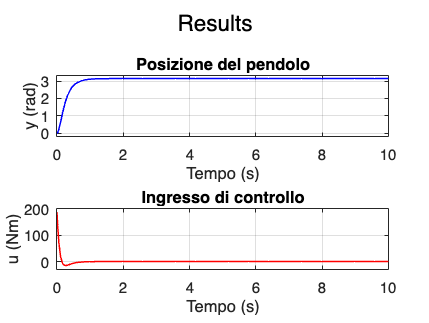

standard_model = 'WP2PolePlacement.slx';
open_system(standard_model);
data = sim(standard_model, 10);
plot_data(data, "WP2PolePlacement");
saveas(gcf, 'Risultati Pole Placement/plot_result.png');

#### Analisi

results=stepinfo(data.y,data.t);
disp('Step Information for the Output');

Step Information for the Output


disp(results);

         RiseTime: 0.4827
    TransientTime: 0.8864
     SettlingTime: 0.8864
      SettlingMin: 2.8790
      SettlingMax: 3.1416
        Overshoot: 0
       Undershoot: 0
             Peak: 3.1416
         PeakTime: 7.5771

